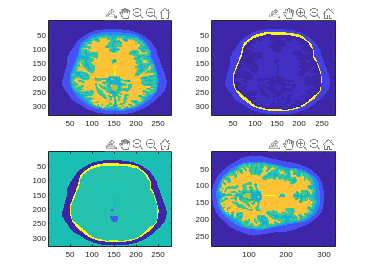

load 198451.mat;
brain_slice_1 = tissueMatrix(:,: ,100);
c_slice = brain_slice_1;
rho_slice = brain_slice_1;

%imagesc(brain_slice_1);

If tissueID = 0 - voxel is air
If tissueID = 1 - voxel is skin
If tissueID = 2 - voxel is skull
If tissueID = 3 - voxel is cerebrospinal fluid
If tissueID = 4 - voxel is grey matter
If tissueID = 5 - voxel is cerebellum
If tissueID = 6 - voxel is white matter
If tissueID = 7 - voxel is ventricles

c_slice(c_slice == 0) = 1500;
c_slice(c_slice == 1) = 1624;
c_slice(c_slice == 2) = 2814;
c_slice(c_slice == 3) = 1504;
c_slice(c_slice == 4) = 1505;
c_slice(c_slice == 5) = 1537;
c_slice(c_slice == 6) = 1553;
c_slice(c_slice == 7) = 1505;

rho_slice(rho_slice == 0) = 1020;
rho_slice(rho_slice == 1) = 92;
rho_slice(rho_slice == 2) = 1908;
rho_slice(rho_slice == 3) = 4;
rho_slice(rho_slice == 4) = 1045;
rho_slice(rho_slice == 5) = 400;
rho_slice(rho_slice == 6) = 1042;
rho_slice(rho_slice == 7) = 1007;

brain_slice_1 = flip(brain_slice_1');;
c_slice = flip(c_slice',1);
rho_slice = flip(rho_slice',1);


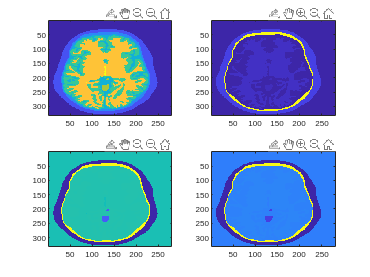

subplot(2,2,1);
imagesc(brain_slice_1);
subplot(2,2,2);
imagesc(c_slice);
subplot(2,2,3);
imagesc(rho_slice);
subplot(2,2,4);
imagesc(c_slice.*rho_slice);

    load MIDA_v1.mat

tissuprop = permute(tissuedistrib,[3,1,2]);
for t =300:400
    pause(1);
    clf;
    h = tissuprop(:,:,t);
    imagesc(h);
end


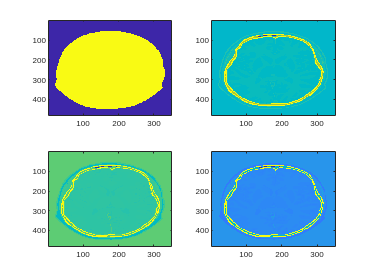

load brain_model2D.mat

tissue_speed_slice(tissue_speed_slice==1440)=1500;
tissue_density_slice(tissue_density_slice==1000)=1200;
tissue_speed_slice=(tissue_speed_slice);;
tissue_density_slice=(tissue_density_slice);

subplot(2,2,1);
imagesc(vstart);
subplot(2,2,2);
imagesc(tissue_speed_slice);
subplot(2,2,3);
imagesc(tissue_density_slice);
subplot(2,2,4);
imagesc((tissue_speed_slice).*(tissue_density_slice));

lambda = 2e-4

lambda = 2.0000e-04

tscan = ScanCartesian('x', [-20e-3:lambda/4:20e-3],'z',[0:lambda/8:60e-3]);

tscan2 = ScanCartesian('x', linspace(-20e-3,20e-3,350),'z',linspace(0, 60e-3,480))

tscan2 =   ScanCartesian with properties:

        x: [-0.0200 -0.0199 -0.0198 -0.0197 -0.0195 -0.0194 -0.0193 -0.0192 -0.0191 -0.0190 -0.0189 -0.0187 -0.0186 -0.0185 -0.0184 -0.0183 -0.0182 -0.0181 -0.0179 -0.0178 -0.0177 -0.0176 -0.0175 -0.0174 -0.0172 -0.0171 -0.0170 -0.0169 -0.0168 … ]
        y: 0
        z: [0 1.2526e-04 2.5052e-04 3.7578e-04 5.0104e-04 6.2630e-04 7.5157e-04 8.7683e-04 0.0010 0.0011 0.0013 0.0014 0.0015 0.0016 0.0018 0.0019 0.0020 0.0021 0.0023 0.0024 0.0025 0.0026 0.0028 0.0029 0.0030 0.0031 0.0033 0.0034 0.0035 0.0036 … ]
    order: 'ZXY'
     size: [480 350 1]
       xb: [-0.0200 0.0200]
       yb: [0 0]
       zb: [0 0.0600]
     nPix: 168000
       dx: 1.1461e-04
       dy: Inf
       dz: 1.2526e-04


med_temp = Medium.Sampled(tscan2, tissue_speed_slice);

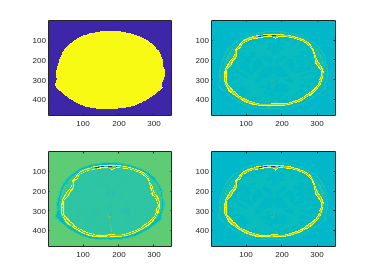

imagesc(tissue_speed_slice);

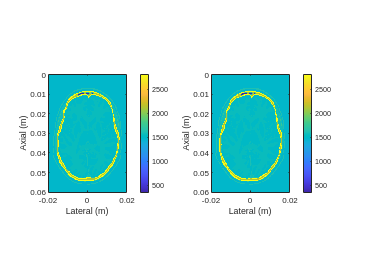

figure;
subplot(1,2,1)
imagesc(med_temp, tscan2,'c'); colorbar;

subplot(1,2,2)
imagesc(med_temp, tscan,'c'); colorbar;

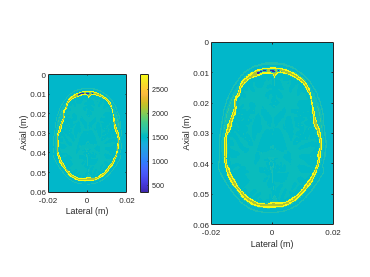

h = imagesc(med_temp,tscan);

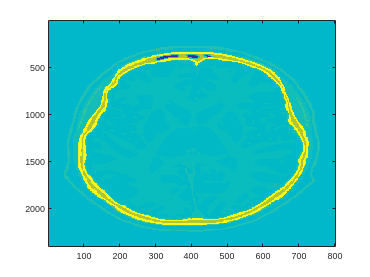

figure;imagesc(imgaussfilt(h.CData))

figure;imagesc(imgaussfilt3(h.CData))

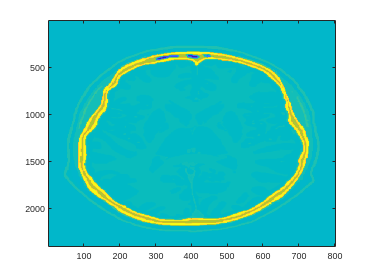

figure;imagesc(imgaussfilt(h.CData,[4 1]))

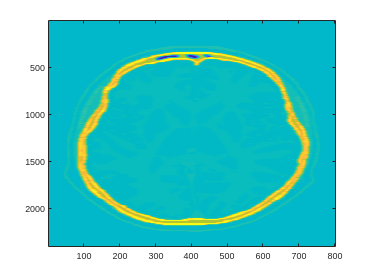

figure;imagesc(imgaussfilt(h.CData,[1 4]))